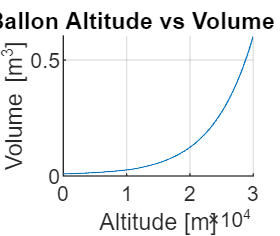

clc
close all

% Experiment 1

% Altitude
alt = 0:30000; %[m]

% Atmoscoesa Function Call
[T,a,P,rho] = atmoscoesa(alt);

% Mass of Balloon + Helium
m = 0.00129 + 0.009569; %[kg]

% Gas Constant
R = 287.5; %[J/kg*K]

% Calculated Volume
V = (m .* T * R)./P; %[m^3]

% 30000 Plot
figure (1);
hold on
grid on
ylabel('Volume [m^3]')
xlabel('Altitude [m]')
title(['Mylar Lifting Ballon Altitude vs Volume ' ...
    'From 0m-30000m'])
plot(alt,V)
hold off

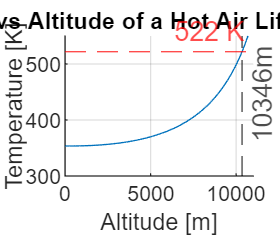


% Experiment 2

% Altitude
alt2 = 0:17500; %[m]

% Atmocoesa Function Call
[T2,a2,P2,rho2] = atmoscoesa(alt2);

% Constants
m_balloon = 0.03; %[kg]
V_given = 0.1314; %[m^3]

% Calculations
T_calc = (P2 * V_given)./(R * ((rho2 .* V_given) - m_balloon)); %[K]

% Max Temperature Plot
figure (2);
hold on
grid on
ylabel('Temperature [K]')
xlabel('Altitude [m]')
title('Temperature vs Altitude of a Hot Air Lifting Gas Balloon')
plot(alt2,T_calc)
xlim([0 11000])
ylim([300 550])

% Find Where Structure Fails
max_alt = find(T_calc>522);
max_alt_ans = max_alt(1,1);

% Finish Plot
xline(max_alt_ans,'k--',{'10346m'})
yline(522,'--r',{'522 K'})
hold off

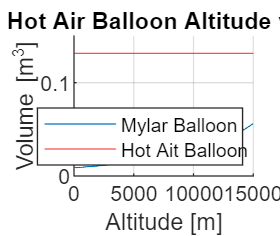


% 15000m Plot
figure (3);
hold on
grid on
ylabel('Volume [m^3]')
xlabel('Altitude [m]')
xlim([0 15000])
title(['Mylar Lifting Ballon and Hot Air Balloon Altitude vs Volume ' ...
    'From 0m-15000m'])
plot(alt,V)
yline(0.1314,'-r')
legend('Mylar Balloon','Hot Ait Balloon','Location','southeast')
hold off